# **Original**


$$z=\left(2i+\left(l-1\right)\right)\frac{L}{2q}$$


Where: $z=f*\frac{L}{2q}$

# **Second Order**


$$f=C_0 \;+C_1 \left(2i+l\right)+C_2 {\left(2i+l\right)}^2$$


i = 0    l = 1     f = 0


$$f=0=C_0 +C_1 +C_2$$


i = q    l = 1     f = 2q


$$f=2q=C_0 +C_1 \left(2q+1\right)+C_2 {\left(2q+1\right)}^2$$


Linearizing this matrix to isolate $C_2$ leads to:


$$\left\lbrack \begin{array}{cc}
1 & 1\\
1 & 2q+1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
C_0 \\
C_1 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0-C_2 \\
2q-C_2 {\left(2q+1\right)}^2 
\end{array}\right\rbrack$$


Solving in Matlab:

syms q C_2
A = [1 1 ;
     1 (2*q+1)]

$$A = \left(\begin{array}{cc} 1 & 1\\ 1 & 2\,q+1 \end{array}\right)$$

 B = [0 - C_2 ;
      2*q - C_2*(2*q+1)^2]

$$B = \left(\begin{array}{c} -C_{2}\\ 2\,q-C_{2}\,{\left(2\,q+1\right)}^{2} \end{array}\right)$$

  x = linsolve(A,B)

$$x = \left(\begin{array}{c} C_{2}+2\,C_{2}\,q-1\\ 1-2\,C_{2}\,q-2\,C_{2} \end{array}\right)$$

Plug in $C_0$ and $C_1$ into $f$


$$f=C_2 +2C_2 q-1+\left(2i+l\right)\left(1-2C_2 q-2C_2 \right)+{\left(2i+l\right)}^2 C_2$$


**Output**

$C_2 =0$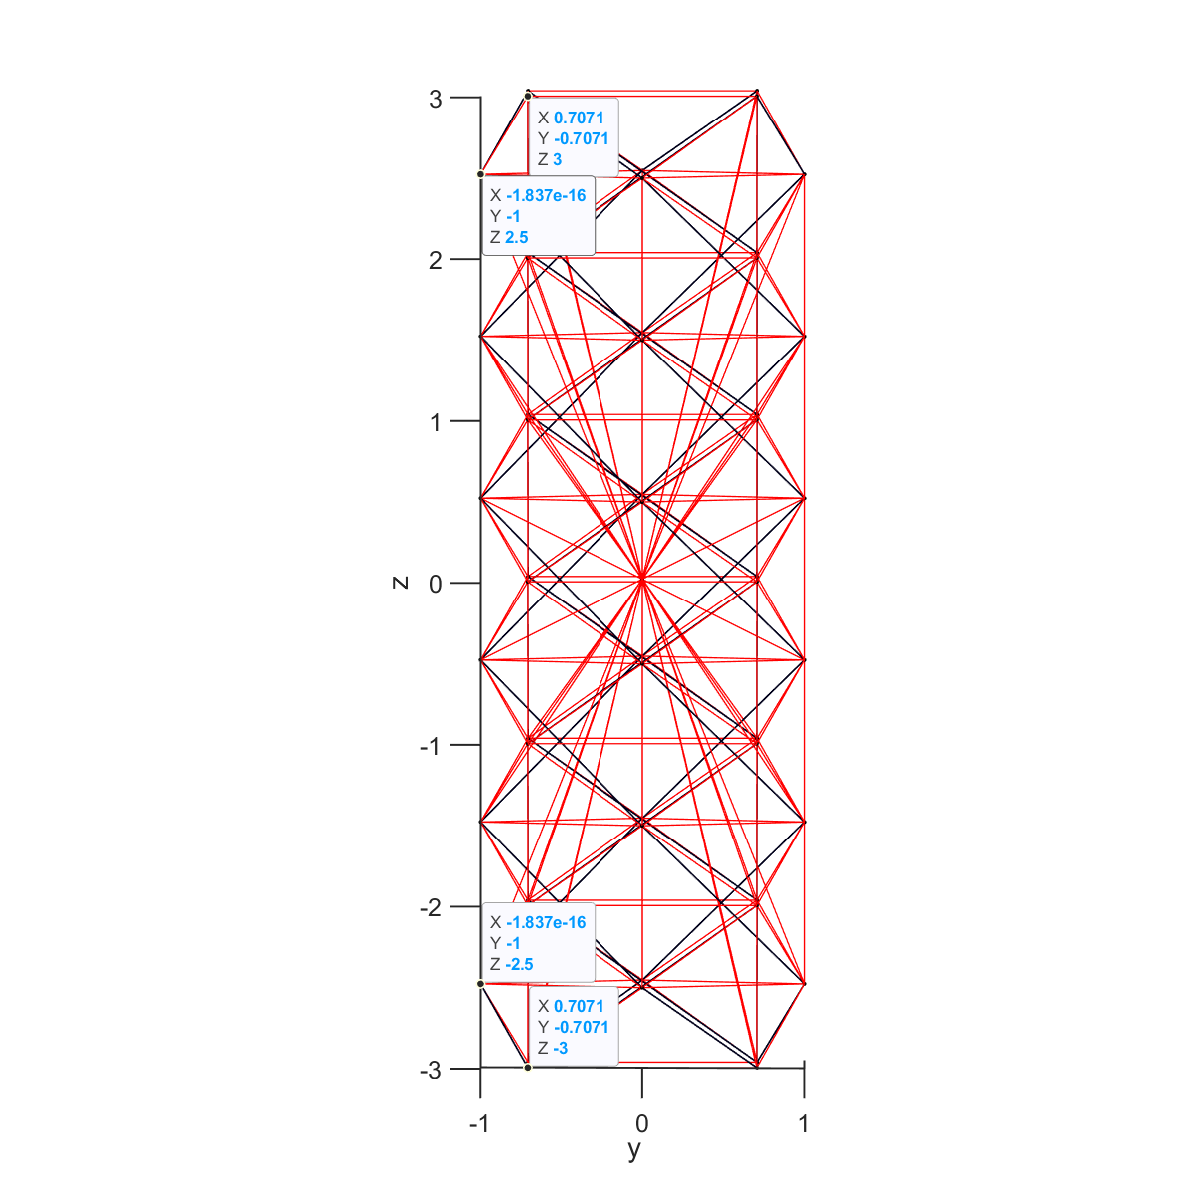

$C_2 =0\ldotp 05$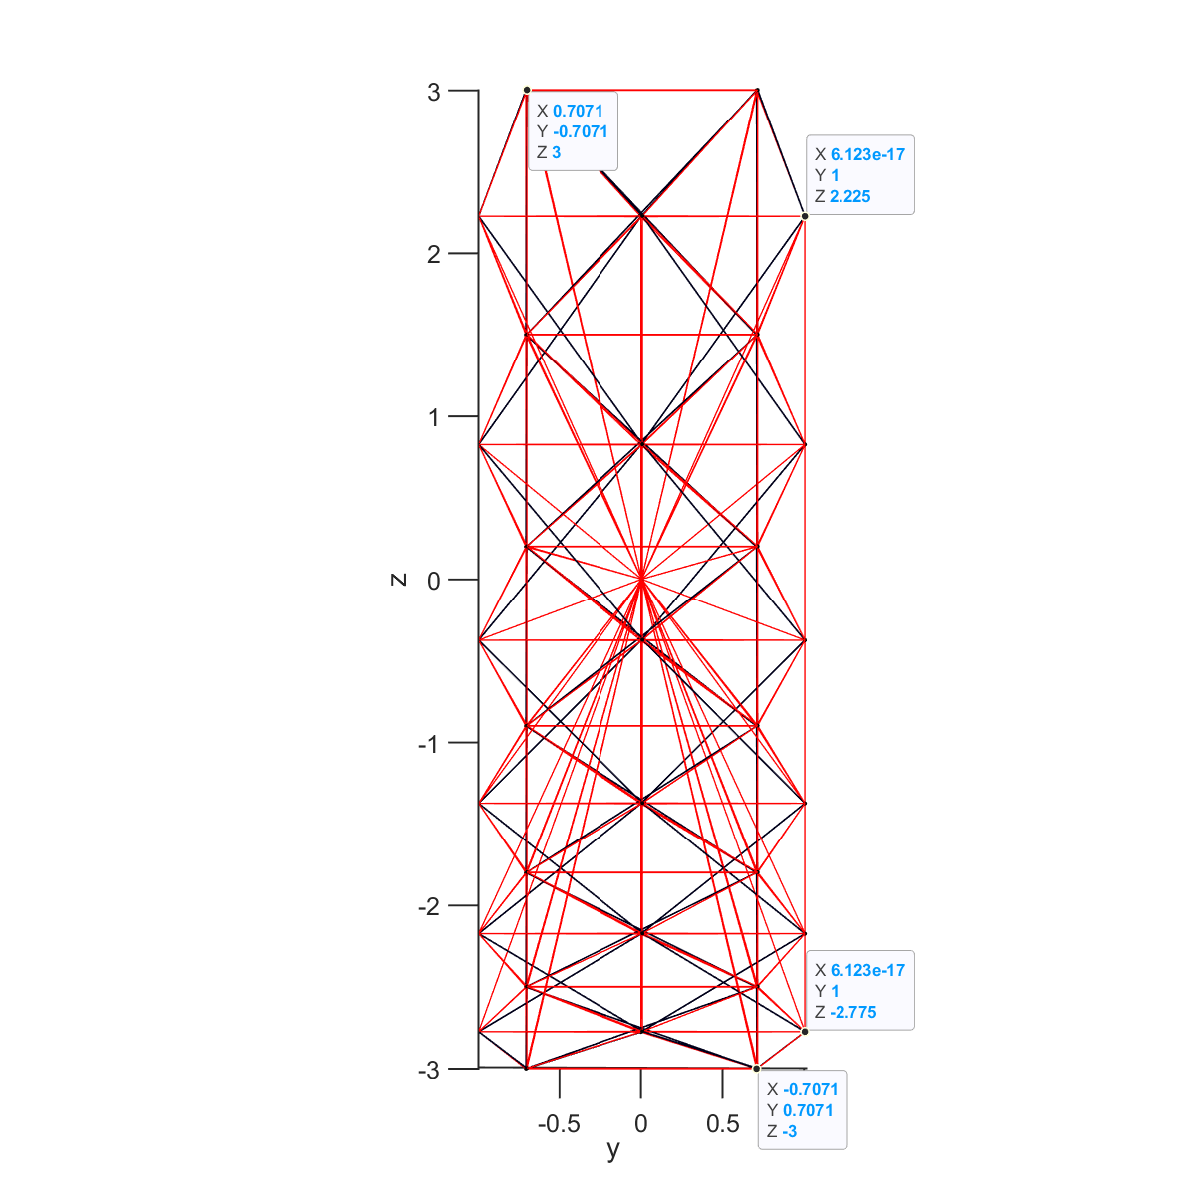$C_2 =-0\ldotp 05$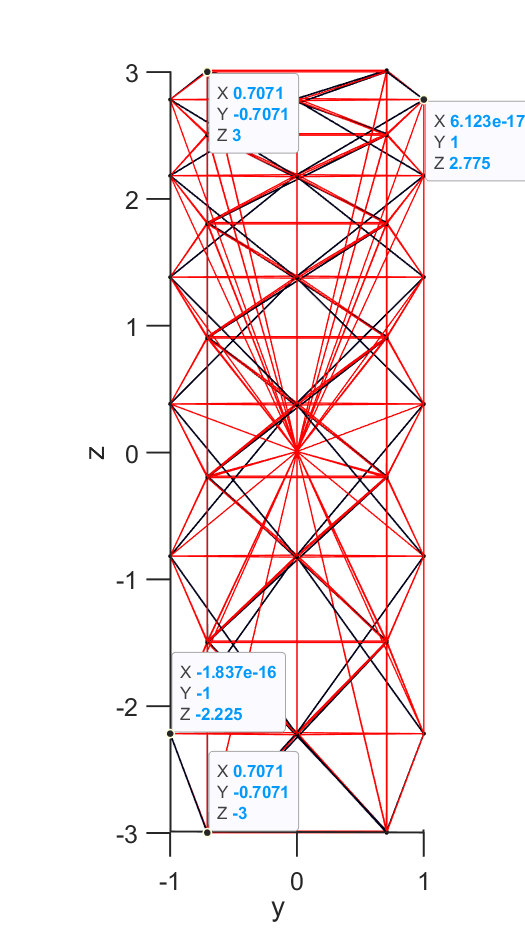

# **Third Order**


$$f=C_0 \;+C_1 \left(2i+l\right)+C_2 {\left(2i+l\right)}^2 +C_3 {\left(2i+l\right)}^3$$


i = 0    l = 1     f = 0


$$f=0=C_0 +C_1 +C_2 \;+C_3$$


i = q    l = 1     f = 2q


$$f=2q=C_0 +C_1 \left(2q+1\right)+C_2 {\left(2q+1\right)}^2 +C_3 {\left(2q+1\right)}^3$$


Linearizing this matrix to isolate $C_3$ leads to:


$$\left\lbrack \begin{array}{ccc}
1 & 1 & 1\\
1 & 2q+l & {\left(2q+1\right)}^2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
C_0 \\
C_1 \\
C_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-C_3 \\
2q-C_3 {\left(2q+1\right)}^3 
\end{array}\right\rbrack$$


For symmetry, we can set $C_2 =\;0$


$$\left\lbrack \begin{array}{ccc}
1 & 1 & 0\\
1 & 2q+1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
C_0 \\
C_1 \\
C_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-C_3 \\
2q-C_3 {\left(2q+1\right)}^3 
\end{array}\right\rbrack$$


Solving in Matlab:

clear; 
  syms C_3 q C_2
  A = [1 1 ; 
     1 (2*q+1)]

$$A = \left(\begin{array}{cc} 1 & 1\\ 1 & 2\,q+1 \end{array}\right)$$

 B = [-C_3-C_2;
      2*q - C_2*(2*q+1)^2 - C_3*(2*q + 1)^3]

$$B = \left(\begin{array}{c} -C_{2}-C_{3}\\ 2\,q-C_{2}\,{\left(2\,q+1\right)}^{2}-C_{3}\,{\left(2\,q+1\right)}^{3} \end{array}\right)$$

  x = linsolve(A,B)

$$x = \left(\begin{array}{c} C_{2}+2\,C_{3}+2\,C_{2}\,q+6\,C_{3}\,q+4\,C_{3}\,q^{2}-1\\ 1-3\,C_{3}-2\,C_{2}\,q-6\,C_{3}\,q-4\,C_{3}\,q^{2}-2\,C_{2} \end{array}\right)$$

Plug in $C_0$ and $C_1$ into $f$


$$f=C_0 \;+C_1 \left(2i+l\right)+C_2 {\left(2i+l\right)}^2 +C_3 {\left(2i+l\right)}^3$$



$$f=$$
 
$$C_2 +2C_3 +2C_2 q+6C_3 q+4C_3 q^2 -1+\left(1-3C\_3-2C\_2q-6C\_3q-4C\_3qˆ2-2C\_2\right)\left(2i+l\right)+C_3 {\left(2i+l\right)}^3$$


$C_3 =0$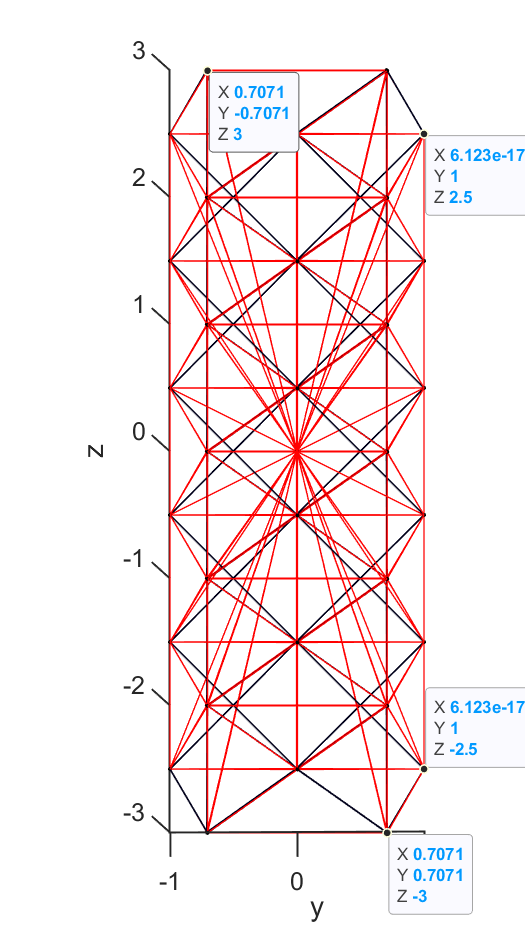

$C_3 =0\ldotp 01$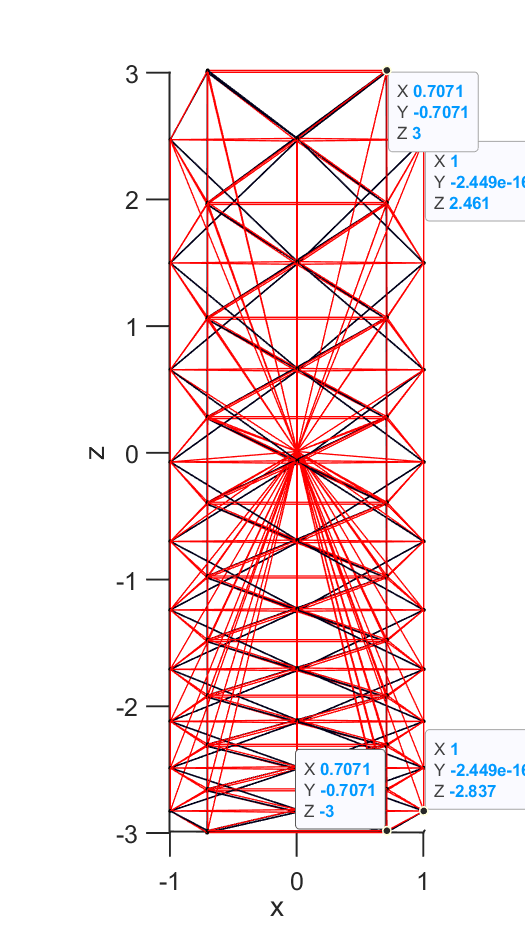$C_3 =-0\ldotp 01$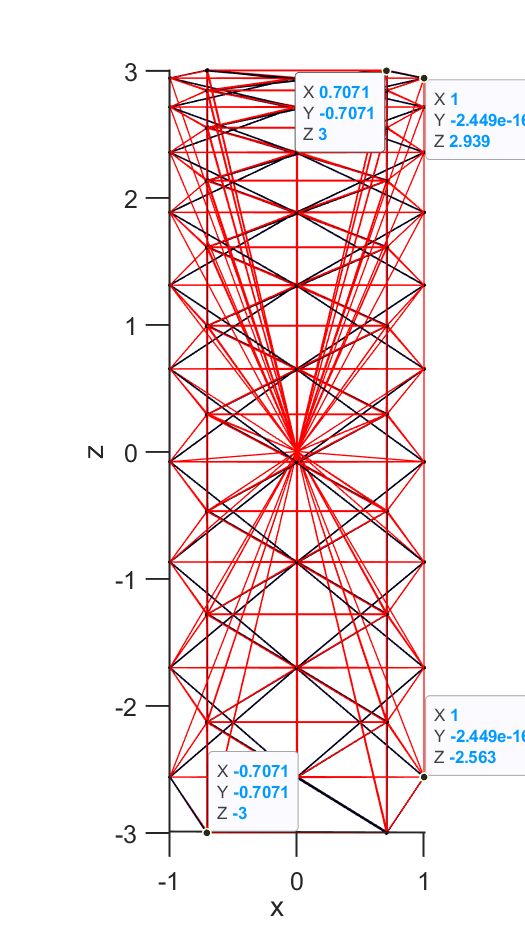

what in the world.